# Higher Order Power Iteration (HOPI) Method 

## Problem 1

Let us define a third-order tensor $\underline{\mathbf{X}} \in R^{5\times 5\times 5}$, where the unitary-norm vectors $\mathbf{u}\in R^5$, $\mathbf{v}\in R^5$, and $\mathbf{w}\in R^5$ and the scalar $\sigma \in R$ are the rank-1 approximation of $\underline{\mathbf{X}}$. It is possible to show that these values are related to the stationary points of the Rayleigh Quotient, that is,


$$\psi_{\underline{\mathbf{X}} } \left(\mathbf{u},\mathbf{v},\mathbf{w}\right)=\frac{{\mathbf{u}}^{\mathrm{T}} {\left\lbrack \underline{\mathbf{X}} \right\rbrack }_{\left(1\right)} \left(\mathbf{w}\otimes \mathbf{v}\right)}{\left\|\mathbf{u}\right\|\left\|\mathbf{v}\right\|\;\left\|\mathbf{w}\right\|}=\frac{{\mathbf{v}}^{\mathrm{T}} {\left\lbrack \underline{\mathbf{X}} \right\rbrack }_{\left(2\right)} \left(\mathbf{w}\otimes \mathbf{u}\right)}{\left\|\mathbf{u}\right\|\left\|\mathbf{v}\right\|\;\left\|\mathbf{w}\right\|}=\frac{{\mathbf{w}}^{\mathrm{T}} {\left\lbrack \underline{\mathbf{X}} \right\rbrack }_{\left(2\right)} \left(\mathbf{v}\otimes \mathbf{u}\right)}{\left\|\mathbf{u}\right\|\left\|\mathbf{v}\right\|\;\left\|\mathbf{w}\right\|}$$


The singular vectors shall satisfy the following equations:


$$\begin{array}{l}
\underline{\mathbf{X}} \;\times_1 \mathbf{u}\times_2 \mathbf{v}=\sigma \;\mathbf{w},\textrm{where}\;\left\|\mathbf{w}\right\|=1\\
\underline{\mathbf{X}} \;\times_1 \mathbf{u}\times_3 \mathbf{w}=\sigma \;\mathbf{v},\textrm{where}\;\left\|\mathbf{v}\right\|=1\\
\underline{\mathbf{X}} \;\times_1 \mathbf{v}\times_3 \mathbf{w}=\sigma \;\mathbf{u},\textrm{where}\;\left\|\mathbf{u}\right\|=1
\end{array}$$


The HOPI method converges for tensor approximation problems in much more mild conditions when compared to matrix approximation problems.

load HOP.mat

[all_vec, sigma] = hopi(tenA);

Comparing with the original tensor

tenA_hat = outprod(all_vec{:});
nseA = norm(tensor(tenA - tenA_hat))/ norm(tensor(tenA))

nseA = 1.1353e-16

Comparing with the original vectors

nseu = norm(u_orginal - all_vec{1})

nseu = 7.8505e-17

nsev = norm(v_orginal - all_vec{2})

nsev = 1.1444e-16

nsew = norm(w_orginal - all_vec{3})

nsew = 1.2495e-16

Conclusion:

- The uniqueness of the final results

- Rapid convergence

## Problem 2

Let us define $\underline{{\mathbf{X}}_0 } \in C^{5\times 5\times 5}$ as a tensor whose elements randomly drawn from a Normal distribution with mean equal to 0 and variance equal to 1. Consider a noisy term, $\underline{\mathbf{V}}$, with same dimension of $\underline{{\mathbf{X}}_0 }$, whose components come from a normal distribution with the same statistics. Let us further define $\underline{\mathbf{X}} =\underline{{\mathbf{X}}_0 } +\alpha \underline{\mathbf{V}}$ as the noisy version of $\underline{{\mathbf{X}}_0 }$, where $\alpha$ is a parameter that is setted depending on the signal-to-noise ration in the system, given by


$${\textrm{SNR}}_{\textrm{dB}} =10\;\log_{10} \;\left(\frac{{\left\|\underline{{\mathbf{X}}_0 } \right\|}_F^2 }{{\left\|\alpha \underline{\mathbf{V}} \right\|}_F^2 }\right)\to \alpha =\frac{{\left\|{\mathbf{X}}_0 \right\|}_F^{\;} }{{\left\|\underline{\mathbf{V}} \right\|}_F^{\;} }\sqrt{{10}^{-\frac{{\textrm{SNR}}_{\textrm{dB}} }{10}} }$$


Compute the HOPI algorithm for the SNR for the range $\left\lbrack \begin{array}{ccccccc}
0 & 5 & 10 & 15 & 20 & 25 & 30
\end{array}\right\rbrack$ dB  and find the estimation $\underline{\hat{\mathbf{X}} }$ for each signal-to-noise ratio. The normalized mean square error (NMSE), given by


$$\textrm{NMSE}=\frac{1}{1000}\sum_i \frac{{\left\|{\underline{\mathbf{X}} }_0 \left(i\right)-\underline{\hat{\mathbf{X}} } \left(i\right)\right\|}_F^2 }{{\left\|{\underline{\mathbf{X}} }_0 \left(i\right)\right\|}_F^2 }\;,$$


is obtained after 1000 Monte Carlo experiments. The values  of ${\underline{\mathbf{X}} }_0$ and $\underline{\mathbf{V}}$ are generated randomly for each experiment.

max = 5e2;
all_snr = 0:5:30;
all_nmse_X = zeros(length(all_snr), 1);
for snr=all_snr
    nmse_X = 0;
    nmse_all_A = zeros(1,3);
    for i=1:max
        % generating tenX0
        tenX0 = outprod(randn([5,1]), randn([5,1]), randn([5,1]));
        % generating tenX
        tenV = randn(size(tenX0));
        alpha = sqrt(10^(-snr/10)) * norm(tensor(tenX0))/norm(tensor(tenV));
        tenX = tenX0 + alpha*tenV;
        % HOPI
        [all_vec, sigma] = hopi(tenX);
        tenX_hat = sigma*outprod(all_vec{:});
        % NMSE X
        nmse_X_loop = norm(tensor(tenX0 - tenX_hat))/ norm(tensor(tenX0));
        nmse_X = nmse_X + nmse_X_loop;
    end
    all_nmse_X(all_snr==snr) = nmse_X/max;
end

#### Ploting the results

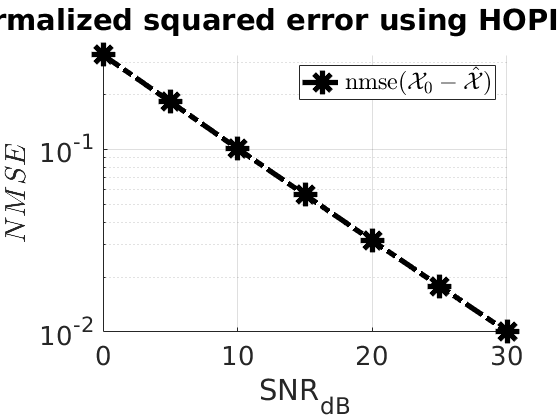

fig = figure();
ax = gca();
ax.FontName = 'Times New Roman';
ax.FontSize = 20;
ax.YAxis.Scale='log';
ax.XAxis.Label.String = 'SNR_{dB}';
ax.YAxis.Label.String = '$$NMSE$$';
ax.YAxis.Label.Interpreter = 'latex';
ax.Title.String = 'The normalized squared error using HOPI vs. SNR_{dB}';
grid on;
hold on;
plot(all_snr, all_nmse_X, 'LineWidth', 4, 'Color', "black","LineStyle","-.","Marker","*","MarkerSize",18);
legend('nmse$$(\mathbf{\mathcal{X}}_0 - \hat{\mathbf{\mathcal{X}}})$$', 'Interpreter','latex');
hold off;

Discussion

- The proper convergence of the values.

function [all_vec, sigma] = hopi(tenX, max_iter, delta_min)
arguments
    tenX;
    max_iter double = 1e3;
    delta_min double = 1e-3;
end
nse_current = inf;
all_vec_new = cell(1, ndims(tenX));
[~, all_U, ~] = thosvd(tenX);
all_vec_new(2:end) = cellfun(@(x)x(:,1), all_U(2:end), 'UniformOutput', false);
for iter=1:max_iter
    for i=1:ndims(tenX)
        all_vec_new{i} = reshape(nmodeproduct(tenX, cellfun(@(x)reshape(x,1,[]), all_vec_new(setdiff(1:ndims(tenX), i)), 'UniformOutput', false), num2cell(setdiff(1:ndims(tenX), i))),[], 1);
        sigma_new = sqrt(sum(abs(all_vec_new{i}.^2)));
        all_vec_new{i} = bsxfun(@rdivide,all_vec_new{i},sigma_new);
        if all_vec_new{i}(1) < 0
            sigma_new = -1*sigma_new;
            all_vec_new{i} = -1* all_vec_new{i};
        end
    end
    nse_new = norm(tensor(tenX - outprod(all_vec_new{:})))/norm(tensor(tenX));
    if nse_new < nse_current
        aux = nse_current;
        nse_current = nse_new;
        all_vec = all_vec_new;
        sigma = sigma_new;
        if aux-nse_new < delta_min % iteration has converged, break it
            break;
        end
    else
        break;
    end
end
end